# *******************               Antenna Array Processing               *******************

## **************                                                   HW10                                                  **************

***********************************       Mohammadreza Arani         :::::::::::::         810100511       ***********************************

*****************************************************************       1401/09/20       *****************************************************************    

close all; clear; clc;

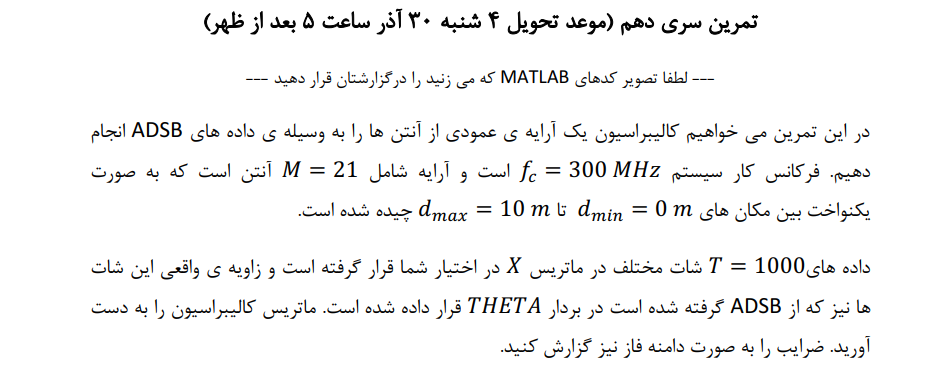

% ADSB Data given:
ADSB_Data = load("hw10.mat");

fc = 300e+06; % 300 MHz

M =21;

d_min = 0;
d_max= 10;

D = linspace(d_min , d_max, M); % Antenna Position Vector over Z-Axis
D  = D'; % A column Vector

% T = 1000; % Shots -- >> in X -- >> Given
% Theta -- >>  True angles


% Find Calibration Matrix! 

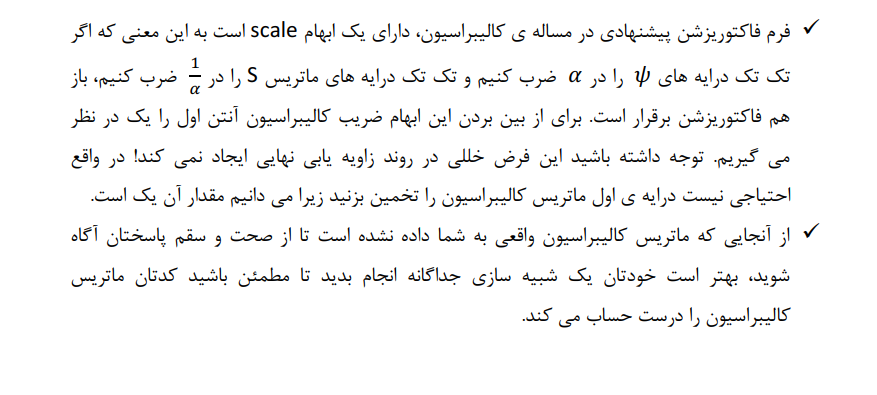


c = 3e+08; % Light Speed in Air;

Lambda = c/fc; % Wave Length


K = 2*pi/Lambda; % Wave Number

Shots       = ADSB_Data.X;
True_Angles = ADSB_Data.THETA;

T = length(Shots);

Theta = 0 : 0.05 : 90 ; % Elevation Angle


MAP1 = exp(1j*K*D*sin(Theta*pi/180)) ;
MAP = MAP1 ./sqrt(sum(abs(MAP1).^2)) ;

## CAlibration Phase:

As mentioned in the lectures, we can model the calibration problem as multiplication of a diagnal matrix and the steering vector as shown below:

$X=\psi \left\lbrack a\left(\theta =0\ldotp 001\right)\;;\ldotp \ldotp \ldotp ;a\left(\theta =90\right)\right\rbrack \left\lbrack \begin{array}{c}
0\\
0\\
\ldotp \\
\ldotp \\
\ldotp \\
A\\
0
\end{array}\right\rbrack$ ;   ---  >>> if $\psi$ was known, we could easily solve the sparse recovery problem using 3 proposed methods.

We can use given ADSB data and obtain the elevation angle from given amplitude and use it in the equation below:

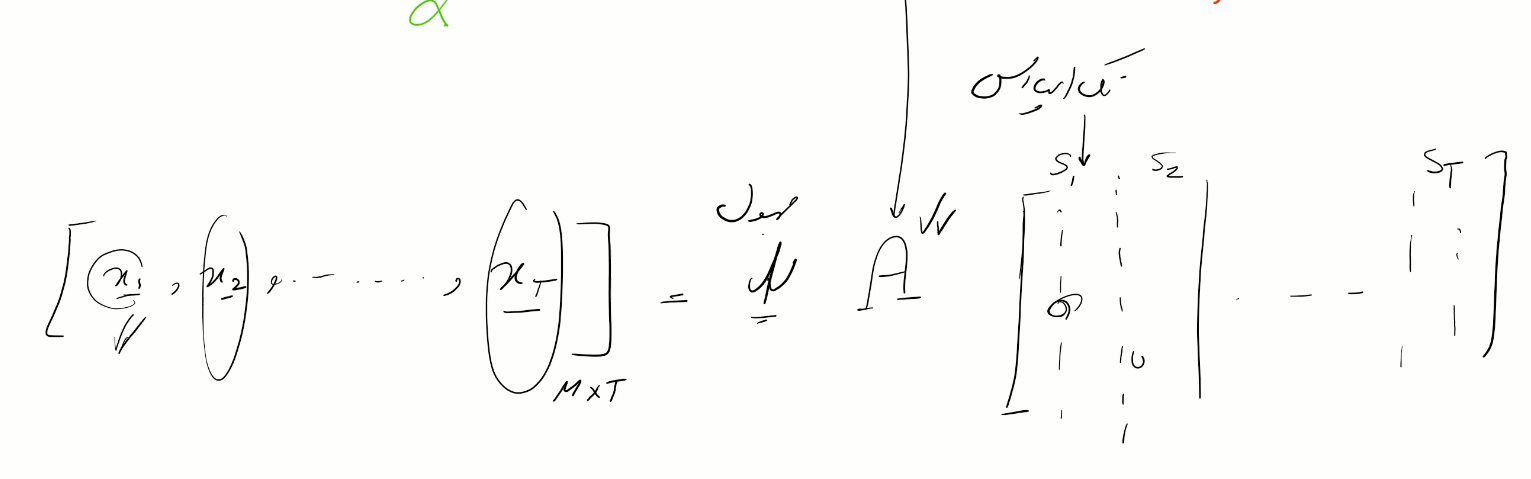

The proposed algorithm in which we can obtain the true value of $\psi$ is called: 

"***Alternation Minimization***"  

                                -- >> an iterative method to reach the global minimum which guarantees the **convergence** in convex problems.

The algorithm works like:

- Initialize  $\psi$ and then find S.

- Using Obtaind S, find optimum $\psi$.

- do over until convergence!

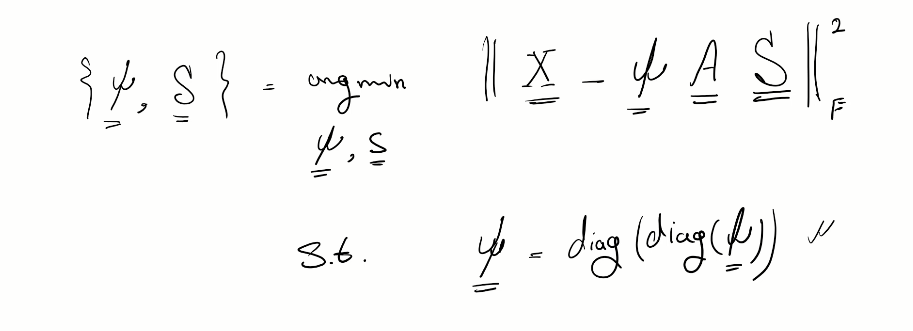

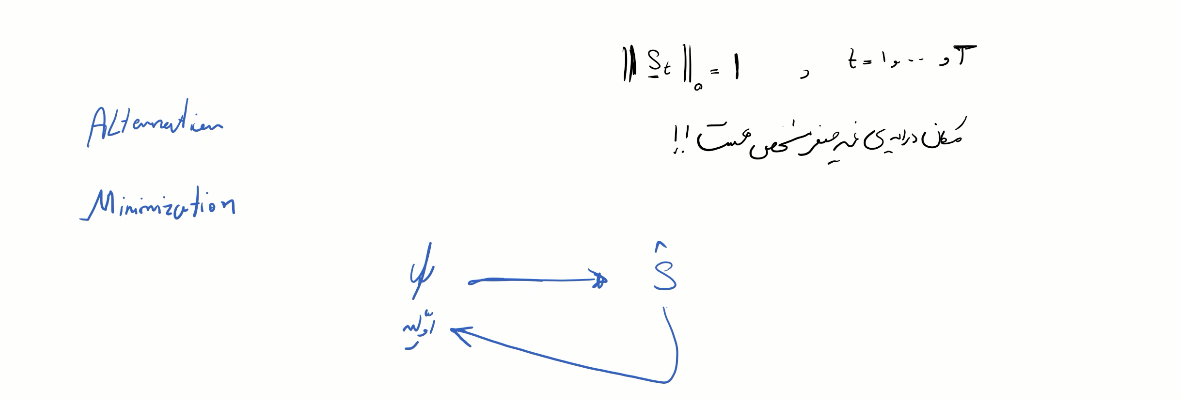

% Init PSI:
PSI  = diag(diag(randn(M)));

% Find Elevation Angles:

%S_indexes = find( (Theta-Theta(1)) == True_Angles'  );

% [val,S_indexes]=intersect(Theta-Theta(1),True_Angles) ; % gives common val and its position in 'Theta'

[idx,S_indexes] = ismember(True_Angles,Theta);
S = zeros(length(Theta),T);

MAX_Iter = 100;
Threshold =1e-2;

for i=1:MAX_Iter

   for p = 1 : T
%        Chooser_mat = zeros(M,1);
%        Chooser_mat(randi(M),1) = 1;

        cvx_begin quiet
            variables S_R(1,1) S_I(1,1) % Consider the S as a Complex Number!

                S_temp = S_R + 1j*S_I;
                minimize(  norm( Shots(:,p) - PSI*MAP(:,S_indexes(p)).*repmat(S_temp,M,1).*(1 ) )  ); % Minimze the objective function...
        
                cvx_end
        S(S_indexes(p), p) = S_temp; % Update S based on the optimum answer!
   end


    for num_element = 1 : M
        cvx_begin quiet
                variables psi_R(1,1) psi_I(1,1)
                    PSI_temp = (psi_R + 1j*psi_I);
                    minimize(norm( Shots(num_element,:) - PSI_temp*MAP(num_element,:)*S )); % Minimize the objective based on optimum S
        cvx_end
        PSI(num_element,num_element) = PSI_temp; % Update PSI based on the optimum PSI!

    end

Error =  sum( abs( Shots - PSI*MAP*S ) ) ; 

if(Error < Threshold)
    break;
end

end

%%%%%
% The ALgorithm Converged with maximum error of:
disp(max(max(Error)));

   8.9462e-07



## FInding Amplitude and angles of PSI:

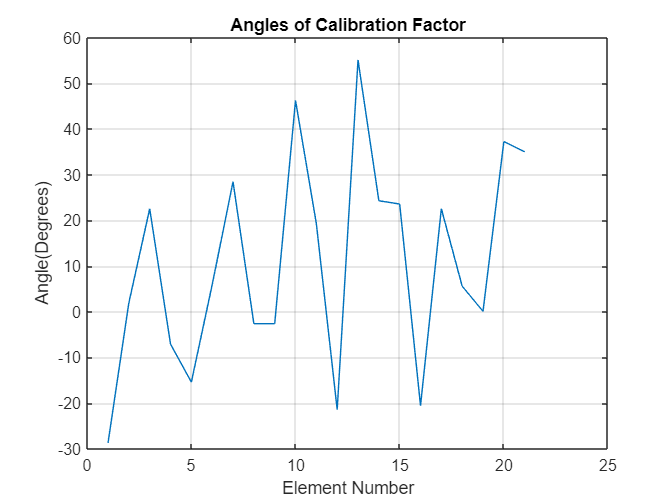

figure(1)
plot(1:M , 180*angle(diag(PSI))/pi )
title("Angles of Calibration Factor");
xlabel("Element Number")
ylabel("Angle(Degrees)")
grid on

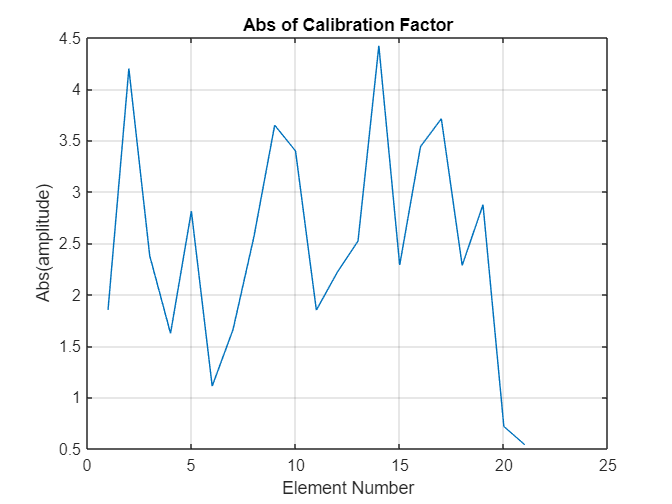

figure(2)
plot(1:M , abs(diag(PSI)) )
title("Abs of Calibration Factor");
xlabel("Element Number")
ylabel("Abs(amplitude)")
grid on

## Test the SAI:


T  =1000;
f1 = 1:T; 
f1 = f1(randperm(length(f1)));

location = f1;


S_test =  zeros(M,T);

for i=1:T

    s = S(:,i);
    l = location(i);
    s(l) = rand(1) + 1j*rand(1); % Complex Random Variable
    S(:,i) = s;

end

SAI_test = diag(diag(rand(M)+1j*rand(M)));
X = SAI_test*MAP*S;



## Now Run the Algo for this given X:

PSI_test  = diag(diag(randn(M)));

Shots_test = X ;

% [idx,S_indexes] = ismember(True_Angles,Theta);
S_indexes_test = location ;
S = zeros(length(Theta),T);

MAX_Iter = 100;
Threshold =1e-2;

for i=1:MAX_Iter

   for p = 1 : T
%        Chooser_mat = zeros(M,1);
%        Chooser_mat(randi(M),1) = 1;

        cvx_begin quiet
            variables S_R(1,1) S_I(1,1) % Consider the S as a Complex Number!

                S_temp = S_R + 1j*S_I;
                minimize(  norm( Shots_test(:,p) - PSI*MAP(:,S_indexes_test(p)).*repmat(S_temp,M,1).*(1 ) )  ); % Minimze the objective function...
        
                cvx_end
        S(S_indexes_test(p), p) = S_temp; % Update S based on the optimum answer!
   end


    for num_element = 1 : M
        cvx_begin quiet
                variables psi_R(1,1) psi_I(1,1)
                    PSI_temp = (psi_R + 1j*psi_I);
                    minimize(norm( Shots_test(num_element,:) - PSI_temp*MAP(num_element,:)*S )); % Minimize the objective based on optimum S
        cvx_end
        PSI_test(num_element,num_element) = PSI_temp; % Update PSI based on the optimum PSI!

    end

Error_test =  sum( abs( Shots_test - PSI_test*MAP*S ) ) ; 

if(Error_test < Threshold)
    break;
end

end



disp(max(max(Error_test)));

   14.0986



disp(min(min(Error_test)));

    1.7163



For 3 runs, we can get the most from calibration accuracy. -- >>  The maximum Error is equal to 14 and the minimum error is 1.71.

The behaviour is almost imitated in the approximated PSI! -- >> and these happens only after 3 consecutive runs! given more time, we can get better results!

- Another approach is to solve the obtimization problem manually!

Consider the cost function as:

- 
$$J={\left|X-\psi *A*S\right|}^2 ;$$


- 
$$\frac{\partial }{\partial S}J=\frac{\partial }{\partial S}\left(\left.\;\;\;\left(X-\psi *A*S\right){\left(-\left(\mathrm{SA}\psi \right.\right)}^T +X^T \right)\;\right)\;=0\Rightarrow \frac{\partial }{\partial S}\left\lbrack \;\;{\mathrm{XX}}^T +-{X\left(\mathrm{SA}\psi \right)}^T -\left(\psi *A*{\left.S\right)X}^T +\psi *A*S*{\left(\left(\mathrm{SA}\psi \right.\right)}^T \;\;\right)\;\;\;\right\rbrack =0\Rightarrow$$



$$0-2{A\psi X}^T \;+\;2\psi \mathrm{AS}=0\;\Rightarrow \mathit{\mathbf{S}}=\frac{{\mathit{\mathbf{A}}\psi \mathit{\mathbf{X}}}^{\mathit{\mathbf{T}}} }{\psi \mathit{\mathbf{A}}}\;;\;$$
 

-- >>  we can use this manual solution instead of using CVX toolbox and it works in a blink of an eye!

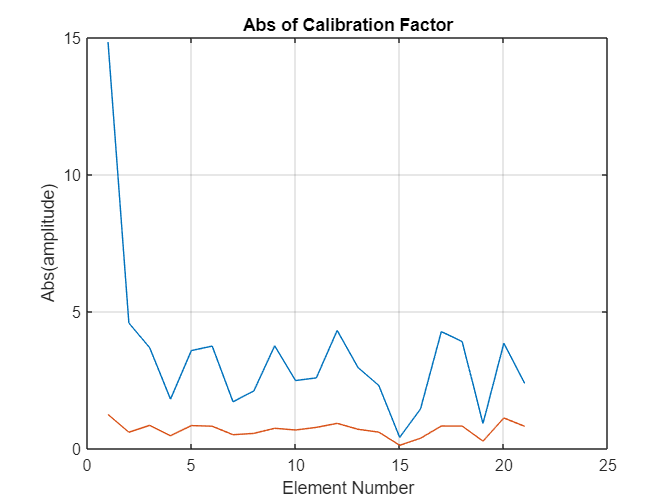

figure(3)
plot(1:M , abs(diag(PSI_test)) )
title("Abs of Calibration Factor");
xlabel("Element Number")
ylabel("Abs(amplitude)")
grid on
hold on
plot(1:M , abs(diag(SAI_test)) )

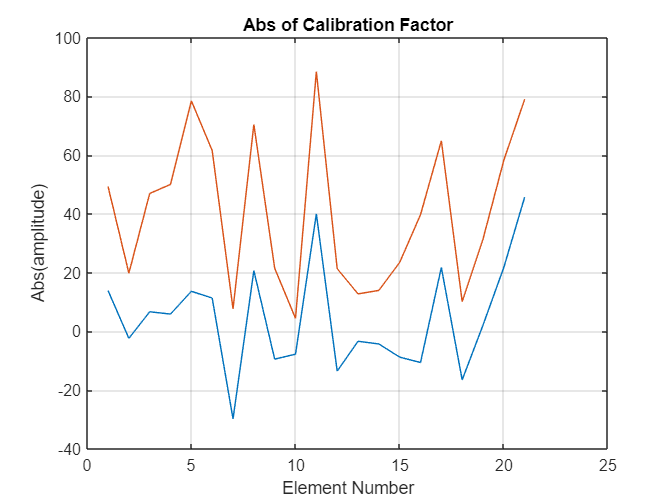

figure(4)
plot(1:M , 180/pi*angle(diag(PSI_test)) );
title("Abs of Calibration Factor");
xlabel("Element Number")
ylabel("Abs(amplitude)")
grid on
hold on
plot(1:M , 180/pi*angle(diag(SAI_test)) );